Окошко для чистки данных:

clear
clc

Задание параметров станции и характеристик гидрофона:

sample_rate         = 32000;     % Hz

M1_amplifier_dB     = 26.0;      % dB
M3_amplifier_dB     = 32.0;      % dB
M1_sensitivity_dB   = -170.0;    % dB re 1V/µPa
M3_sensitivity_dB   = -165.0;    % dB re 1V/µPa

station             = 'M1';

Чтение файла с амплитудно-частотной характеристикой гидрофона в соответсвии с выбранной станцией:

load('AFR.mat', 'f');
ARF_freq = f;
clear f;

if strcmp(station, 'M1')
    load('AFR.mat', 'afrM1');
    AFR = afrM1;
    clear afrM1;
    constant = M1_sensitivity_dB + M1_amplifier_dB;

elseif strcmp(station, 'M3')
    load('AFR.mat', 'afrM3');
    AFR = afrM3;
    clear afrM3;
    constant = M3_sensitivity_dB + M3_amplifier_dB;

else
    error('Unknown station');
end

Рассчет коэффициентов полинома для аппроксимации АЧХ:

- до 100 Гц полином третьей степени с фиксированными точками (0,0) и (100,1) и фиксированной производной в точке f=100

- после 100 Гц полином пятой степени с фиксированной точкой (100,1) и фиксированной производной в точках f=100 и f=16000

first_part_size = 100;
p1 = polyfix(   ARF_freq(1:first_part_size),   AFR(1:first_part_size), 3, [0 100], [0 1],         100,     0);
p2 = polyfix( ARF_freq(first_part_size:end), AFR(first_part_size:end), 5,     100,     1, [100 16000], [0 0]);

Определение исследуемого диапазона времени и чтение соответсвующих файлов: 

                            % ( year, month, day, hour, min, sec)
start_time          = datetime( 2014,     6,  20,    9,  40,   0);
end_time            = datetime( 2014,     6,  20,   10,  10,   0);

duration = end_time - start_time;
files_num = ceil(seconds(duration) / 600);

function fname = file_name(station, start_time, end_time)
    fname = sprintf('%s_%02d%02d%02d%02d-%02d%02d%02d%02d.dat', ...
                    station, ...
                    day(start_time), month(start_time), hour(start_time), minute(start_time), ...
                    day(end_time), month(end_time), hour(end_time), minute(end_time));
end

current_time = start_time;
data_arrays = cell(files_num);

for i = 1:files_num
    next_time = current_time + minutes(10);
    filename = file_name(station, current_time, next_time);
    
    fid = fopen(filename, 'r');
    if fid == -1
        error(['Cannot open file: ' filename]);
    end
    
    samples = fread(fid, inf, 'int16');
    fclose(fid);
    
    data_arrays{i} = single(samples);
    current_time = next_time;
end

data_array = cat(1, data_arrays{:});

Полученный data_array - это биты. 

Для того, чтобы перевести в вольты, проводим калибровку:

- V_max = 0.83 В - значение напряжения, соответсвующее наибольшему биту

- B = 2^15 - наибольшее значение бита ~ разрешение ADC ~ число уровней (вообще, число возможных значений 2^16, но один бит затрачивается на знак, поэтому итоговый диапазон значений [-2^15;2^15] - 1 (для нуля, с одной из сторон))

V_max = 0.83;
B = 2^15;
data_array_V = data_array * V_max / B;
clear V_max;
clear B;
clear data_array;

Задаем параметры окна, которое будет использоваться при расчете преобразования Фурье:

window_size = sample_rate*0.25;
win = hamming(window_size);

Фильтрация низких частот: ОЧЕНЬ ДОЛГО, НИКОГДА НЕ ИСПОЛЬЗОВАТЬ (но такое существует)

% passband_freq = 20;
% data_array_V = highpass(data_array_V, passband_freq, sample_rate);

Получение спектрограммы с помощью spectrogram (нет осреднения по времени):

% % [Zxx, f, t, Pxx] = spectrogram(data_array_V, win, (window_size*0.5), window_size, sample_rate, "psd");

Проверка выполнения теоремы Парсеваля для одного окна:

% % df = f(2) - f(1);  % frequency resolution
% % dt = t(2) - t(1);  % time resolution
% 
% % energy_spectrogram = sum(abs(Pxx(:,1))) * df * dt ;
% % fprintf('Spectrogram Energy in one window: %f\n', energy_spectrogram);
% 
% % energy_direct = sum(abs(data_array_V(1:window_size)).^2) / sample_rate;
% % fprintf('Direct Energy in one window: %f\n', energy_direct);

Проверка выполнения теоремы Парсеваля для всего периода времени:

% energy_spectrogram_full = sum(sum(abs(Pxx),2) * df) * dt;
% fprintf('Full Spectrogram Energy: %f\n', energy_spectrogram_full);
% 
% energy_direct_full = sum(abs(data_array_V).^2) / sample_rate;
% fprintf('Full Direct Energy: %f\n', energy_direct_full);

Проверка выполнения теоремы Парсеваля для нескольких окон:

% n_windows = 200;
% ints    = []*n_windows; % window's number
% values  = []*n_windows; % the difference of direct and spectrogram's energies in each window
% 
% for i=1:200    
%     energy_spectrogram_temp = sum(abs(Pxx(:,i))) * df * dt ;
%     energy_direct_temp = sum(abs(data_array_V((i-1)*window_size+1 : i*window_size)).^2) / sample_rate;
%     ints(i) = i;
%     values(i) = abs(energy_direct_temp-energy_spectrogram_temp)/energy_direct_temp*100;
% end
% 
% figure;
% plot(ints, values);

Получение значений АЧХ на частотах, на которых расчитана спектрограмма:

% y1 = polyval(p1,f(f < first_part_size));
% y2 = polyval(p2,f(f >= first_part_size));
% fr = cat(1,y1,y2);

Поправка значений спектрограммы на АЧХ:

% for k=1:size(Pxx,1)
%     Pxx(k,:)=Pxx(k,:)./(fr(k))^2;
% end

Построение спектрограммы:

% figure('Position', [100, 100, 1000, 600]);
% imagesc(t, f, 10*log10(abs(Pxx)) - constant);
% axis xy;
% ylabel('Frequency [Hz]');
% xlabel('Time [sec]');
% colorbar;
% c = colorbar;
% ylabel(c, 'Spectrogram [dB re 1μPa^2/Hz]');
% title('Spectrogram');
% % saveas(gcf, 'Spectrogram1.png');

Получение спектрограммы с помощью Welch method (есть осреднения по времени):

dt_welch = 60; %sec
t_welch = 0:dt_welch:seconds(duration)-1;

% здесь 4001 - число значений частоты (разрешение) = такое же, как в spectrogram, не зависит от dt_welch
% не обязательно вводить, нужен только для того, чтобы не расширять массив на каждом шаге
Pxx_welch = zeros(4001, ceil(seconds(duration) / dt_welch));

for i=0:ceil(seconds(duration)/dt_welch)-1
    [pxx,f_welch] = pwelch(data_array_V(sample_rate*dt_welch*i+1:sample_rate*dt_welch*(i+1)), win, (window_size*0.5), window_size, sample_rate);
    Pxx_welch(:,i+1) = pxx;
end

Проверка выполнения теоремы Парсеваля для одного dt_welch:

df_welch = f_welch(2)-f_welch(1);

energy_welch = sum(abs(Pxx_welch(:,1))) * df_welch * dt_welch;
fprintf('Welch Energy in one window: %f\n', energy_welch);

Welch Energy in one window: 0.004131



energy_direct = sum(abs(data_array_V(1:sample_rate*dt_welch)).^2) / sample_rate;
fprintf('Direct Energy in one window: %f\n', energy_direct);

Direct Energy in one window: 0.004133


Проверка выполнения теоремы Парсеваля для всего периода времени:

energy_full = sum(sum(abs(Pxx_welch),2) * df_welch) * dt_welch;
fprintf('STFT Energy FULL: %f\n', energy_full);

STFT Energy FULL: 0.096842



energy_direct_full = sum(abs(data_array_V).^2) / sample_rate;
fprintf('Direct Energy FULL: %f\n', energy_direct_full);

Direct Energy FULL: 0.097606


Получение АЧХ на f_welch:

y1 = polyval(p1,f_welch(f_welch < first_part_size));
y2 = polyval(p2,f_welch(f_welch >= first_part_size));
fr = cat(1,y1,y2);

Поправка значений спектрограммы на АЧХ:

for k=1:size(Pxx_welch,1)
    Pxx_welch(k,:)=Pxx_welch(k,:)./(fr(k))^2;
end

Построение спектрограммы:

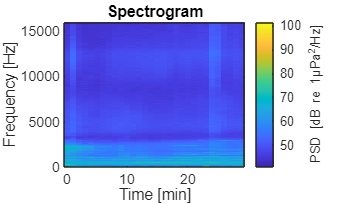

figure('Position', [100, 100, 1000, 600]);
imagesc(t_welch/60, f_welch, 10*log10(abs(Pxx_welch)) - constant);
axis xy;
ylabel('Frequency [Hz]');
xlabel('Time [min]');
colorbar;
c = colorbar;
ylabel(c, 'PSD [dB re 1μPa^2/Hz]');
title('Spectrogram');

% saveas(gcf, 'Spectrogram1.png');

Функция, рассчитывающая SPL для заданной центральной частоты:

function SPL = spl_third_octave(center_freq, pxx, f, constant)
    df = f(2)-f(1);
    lower_limit = center_freq/1.22;
    upper_limit = center_freq*1.22;
    low = find(f>lower_limit,1);
    upp = find(f>upper_limit,1)-1;
    SPL = 10*log10(sum(abs(pxx(low:upp,:)),1)) - constant + 10*log10(df);
end

Расчет и построение на графике SPL для выбранных центральных частот:

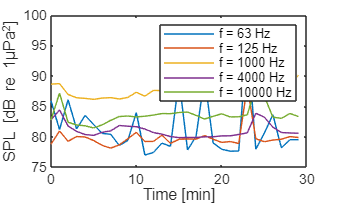

plot(t_welch/60, spl_third_octave(63, Pxx_welch, f_welch, constant),'DisplayName','f = 63 Hz');
hold on

ylabel('SPL [dB re 1μPa^2]')
xlabel('Time [min]')
plot(t_welch/60, spl_third_octave(125, Pxx_welch, f_welch, constant),'DisplayName','f = 125 Hz');
plot(t_welch/60, spl_third_octave(1000, Pxx_welch, f_welch, constant),'DisplayName','f = 1000 Hz');
plot(t_welch/60, spl_third_octave(4000, Pxx_welch, f_welch, constant),'DisplayName','f = 4000 Hz');
plot(t_welch/60, spl_third_octave(10000, Pxx_welch, f_welch, constant),'DisplayName','f = 10000 Hz');
legend
hold off

Функция, рассчитывающая SPL в определенном диапазоне частот: *(можно объединить с spl_third_octave)*

function SPL = spl_band(lower_limit, upper_limit, pxx, f, constant)
    df = f(2)-f(1);
    low = find(f>lower_limit,1);
    upp = find(f>upper_limit,1)-1;
    SPL = 10*log10(sum(abs(pxx(low:upp,:)),1))- constant + 10*log10(df);
end

Сравнение SPL во всем частотном диапазоне, полученный из MSP или Welch:

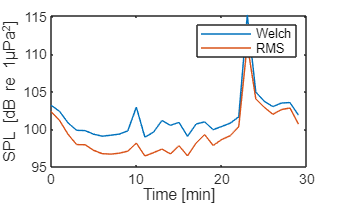

function rms_pressure = rms_pressure(data, dt_welch, duration, sample_rate)
    rms_pressure = []*ceil(seconds(duration)/dt_welch); 
    for i=0:ceil(seconds(duration)/dt_welch)-1
        rms_pressure(i+1) = rms(data(sample_rate*60*i+1:sample_rate*60*(i+1)));

    end
end

SPL_rms = 20*log10(rms_pressure(data_array_V, dt_welch, duration, sample_rate))-constant;
SPL_welch = spl_band(0, 15990, Pxx_welch, f_welch, constant);

plot(t_welch/60, SPL_welch,'DisplayName','Welch');
hold on
ylabel('SPL [dB re 1μPa^2]')
xlabel('Time [min]')
plot(t_welch/60, SPL_rms,'DisplayName','RMS');
legend
hold off

Фильтрация сигнала в некотором диапазоне частот для дальнейшего сравнения SPL:

*(Работает очень долго...)*

data_array_V_100_400 = bandpass(data_array_V, [100 400], sample_rate);
data_array_V_10000_16000 = bandpass(data_array_V, [10000 15900], sample_rate);

Сравнение SPL в низкочастотной и высокочастотной полосе, полученный из MSP или Welch:

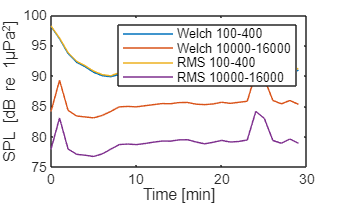

SPL_rms_100_400 = 20*log10(rms_pressure(data_array_V_100_400, dt_welch, duration, sample_rate))-constant;
SPL_rms_10000_16000 = 20*log10(rms_pressure(data_array_V_10000_16000, dt_welch, duration, sample_rate))-constant;

SPL_welch_100_400 = spl_band(100, 400, Pxx_welch, f_welch, constant);
SPL_welch_10000_16000 = spl_band(10000, 15990, Pxx_welch, f_welch, constant);

plot(t_welch/60, SPL_welch_100_400,'DisplayName','Welch 100-400');

hold on
ylabel('SPL [dB re 1μPa^2]')
xlabel('Time [min]')
plot(t_welch/60, SPL_welch_10000_16000,'DisplayName','Welch 10000-16000');
plot(t_welch/60, SPL_rms_100_400,'DisplayName','RMS 100-400');
plot(t_welch/60, SPL_rms_10000_16000,'DisplayName','RMS 10000-16000');
legend
hold off